# **非線形常微分方程式で表された**

# **3バス発電機の内部状態についての時間応答**

## ＜初期設定＞

・応答時間: tspan

・発電機内部状態の初期値: initial_generator_state

・発電機内部状態の定常値: steady_generator_state

clear

tspan = [0 100];

initial_generator_state = [5;2.1;1.1;3;2.1;1;0;0;0];

steady_generator_state = [1;2;1.1;3;2;1.5;0;0;0];

## ＜表示内容＞

・上記初期設定における時間応答のグラフ

 [ δ , E , Δω ] に関して

・初期値と定常値の差: initial_delta 

・最終値と定常値の差: final_delta

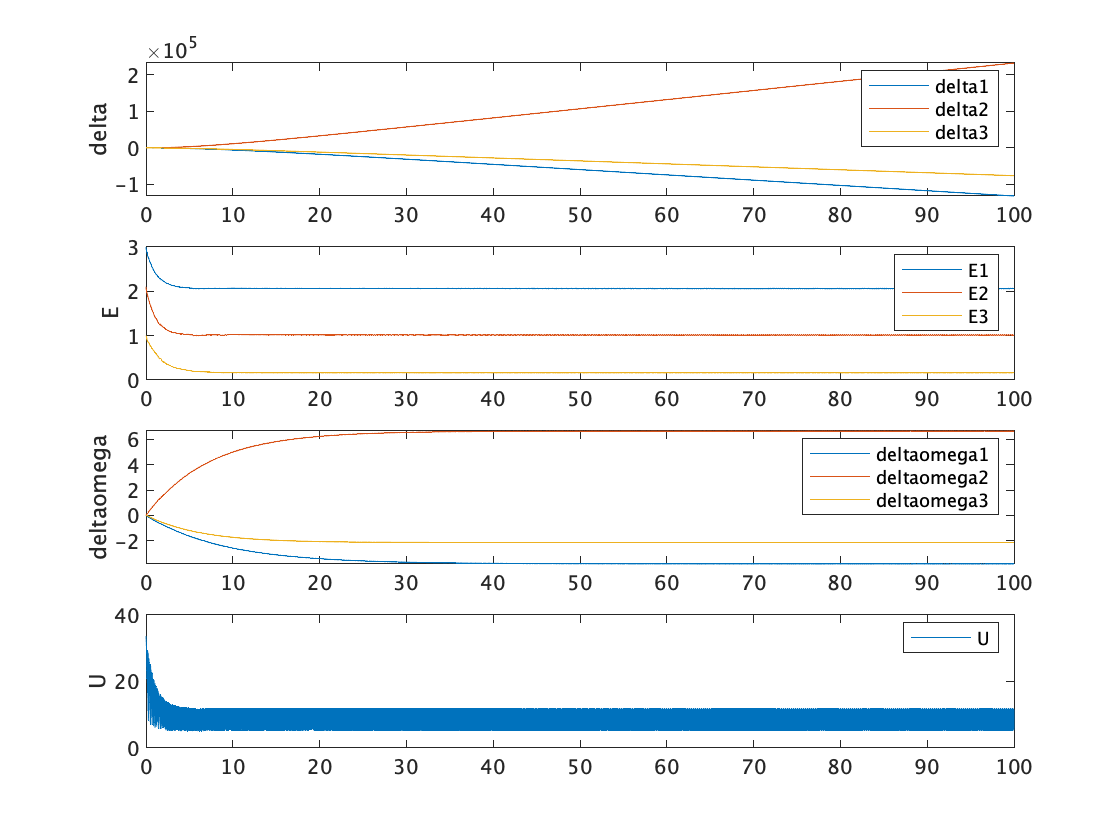

generator_state_ode_solver_for_livescript

initial_error = initial_generator_state - steady_generator_state;
initial_error = reshape(initial_error, 3, 3)

initial_delta =     4.0000         0         0
    0.1000    0.1000         0
         0   -0.5000         0



final_error = transpose([delta(end,:) initial_E(end,:) deltaomega(end,:)]) - steady_generator_state;
final_error = reshape(final_error,3,3)

final_delta = 	1.0e+05 *

   -1.3185   -0.0000   -0.0000
    2.3289   -0.0000    0.0001
   -0.7616   -0.0000   -0.0000


initial_error = initial_generator_state - steady_generator_state;

定常値からの微小偏差による影響

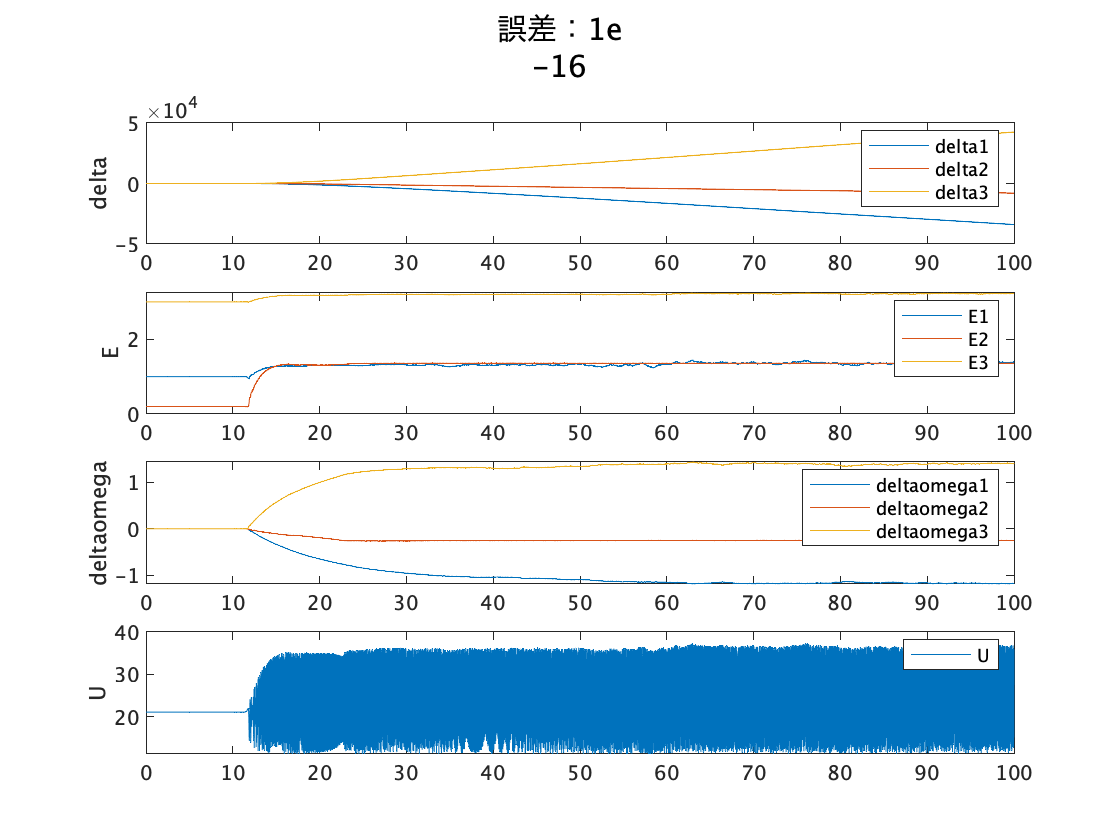

initial_delta = 	1.0e+-15 *

         0    0.1110         0
    0.0971   -0.1110         0
         0         0         0


final_delta = 	1.0e+04 *

   -3.3944    0.0000   -0.0001
   -0.7939    0.0001   -0.0000
    4.2517    0.0000    0.0001


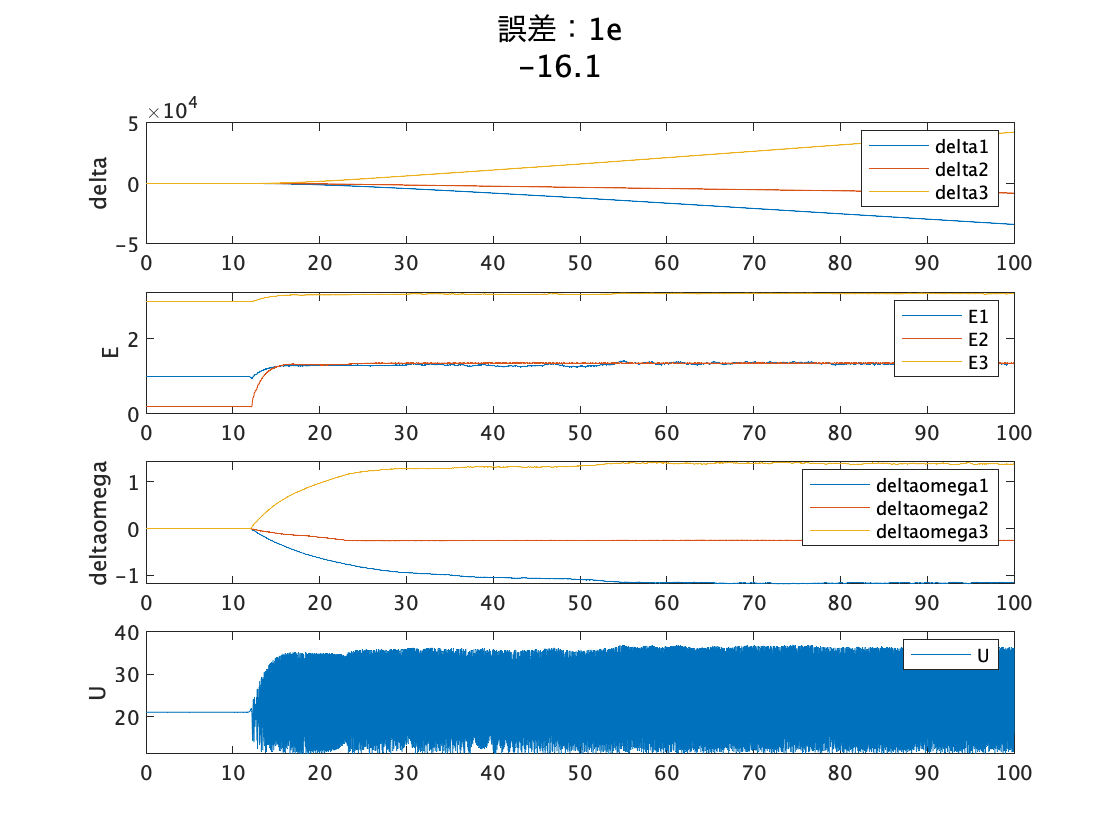

initial_delta = 	1.0e+-15 *

         0    0.1110         0
    0.0833   -0.0833         0
         0         0         0


final_delta = 	1.0e+04 *

   -3.3809    0.0000   -0.0001
   -0.7925    0.0001   -0.0000
    4.2358    0.0000    0.0001


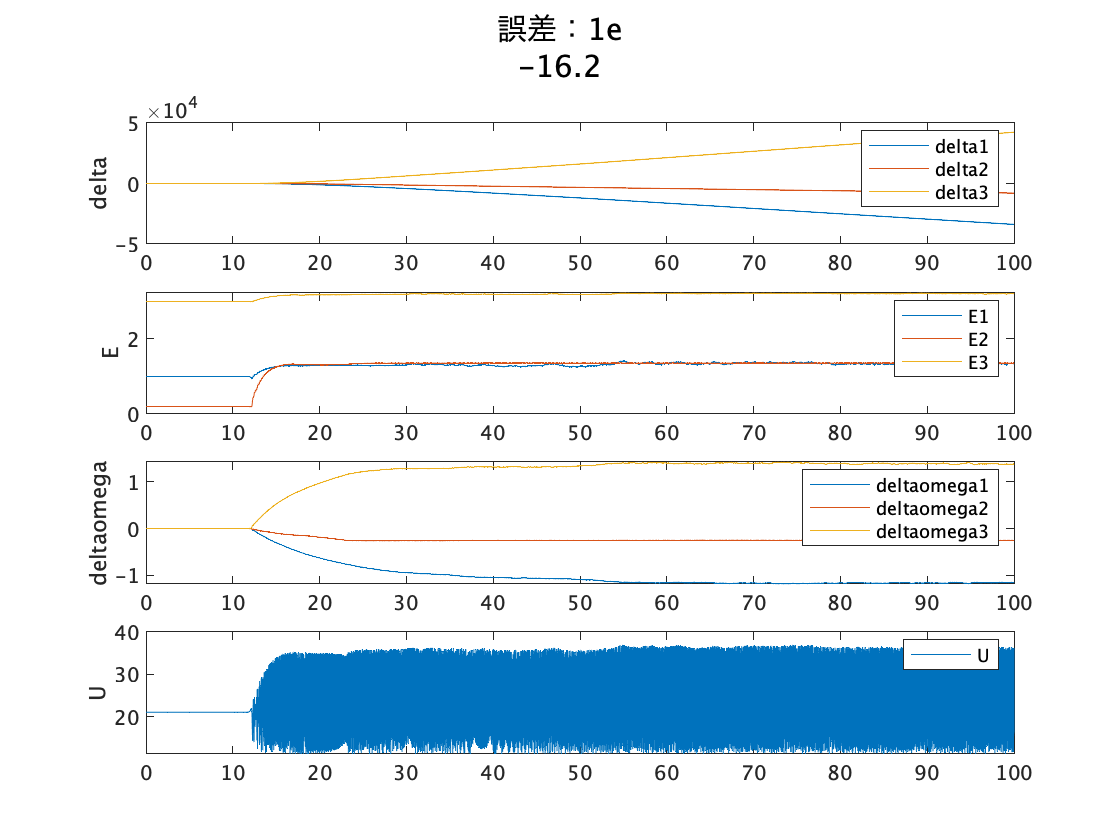

initial_delta = 	1.0e+-15 *

         0    0.1110         0
    0.0694   -0.0555         0
         0         0         0


final_delta = 	1.0e+04 *

   -3.3809    0.0000   -0.0001
   -0.7925    0.0001   -0.0000
    4.2358    0.0000    0.0001


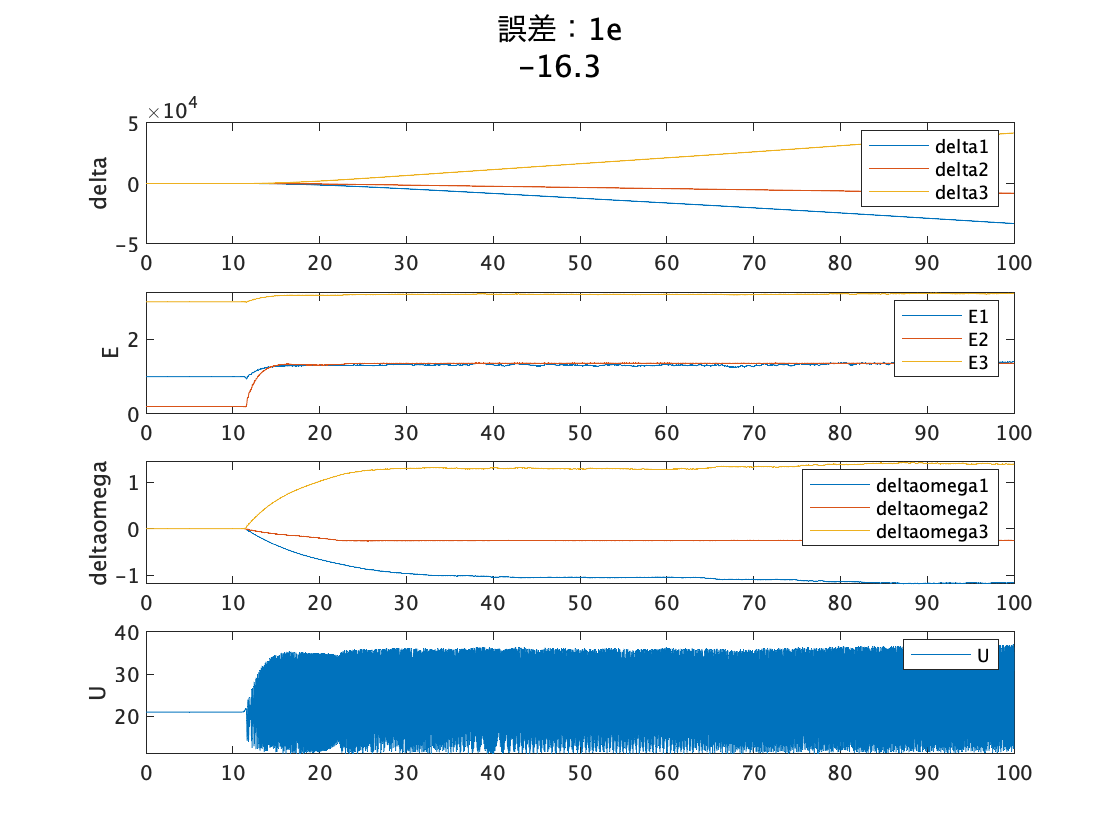

initial_delta = 	1.0e+-16 *

         0         0         0
    0.5551   -0.5551         0
         0         0         0


final_delta = 	1.0e+04 *

   -3.3110    0.0000   -0.0001
   -0.8033    0.0001   -0.0000
    4.1762    0.0000    0.0001


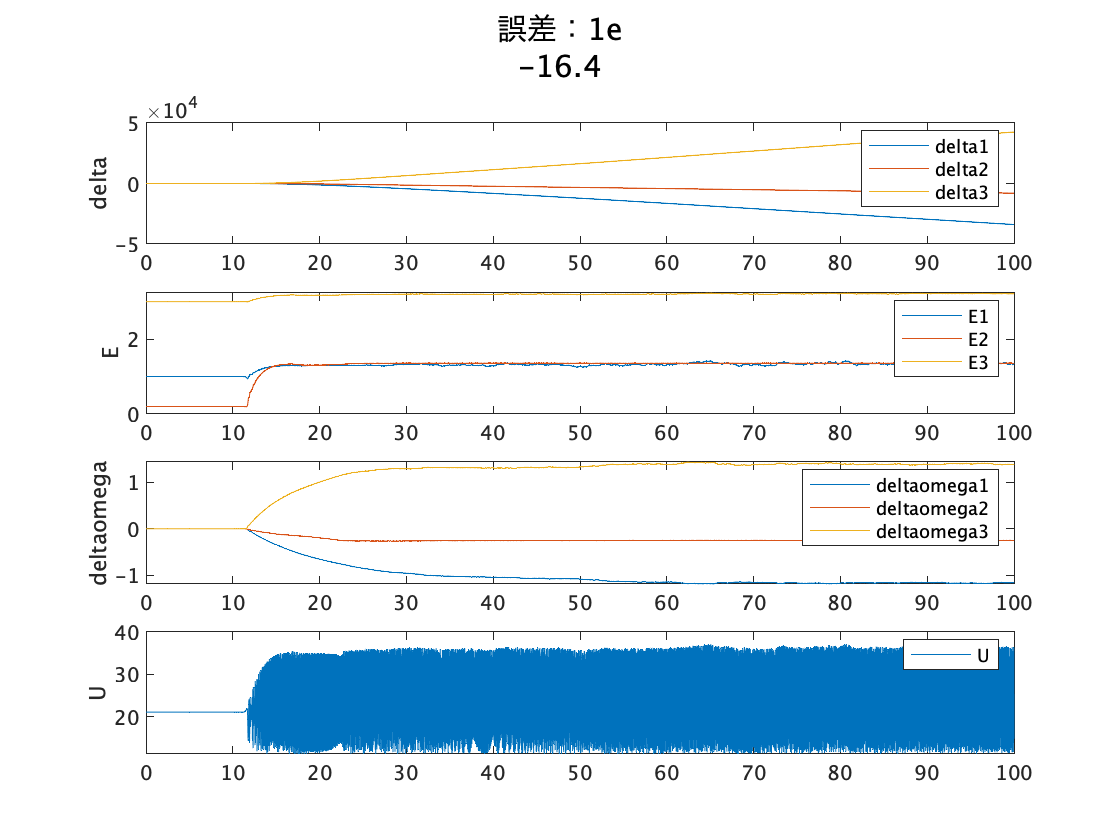

initial_delta = 	1.0e+-16 *

         0         0         0
    0.4163   -0.2776         0
         0         0         0


final_delta = 	1.0e+04 *

   -3.3931    0.0000   -0.0001
   -0.7975    0.0001   -0.0000
    4.2527    0.0000    0.0001


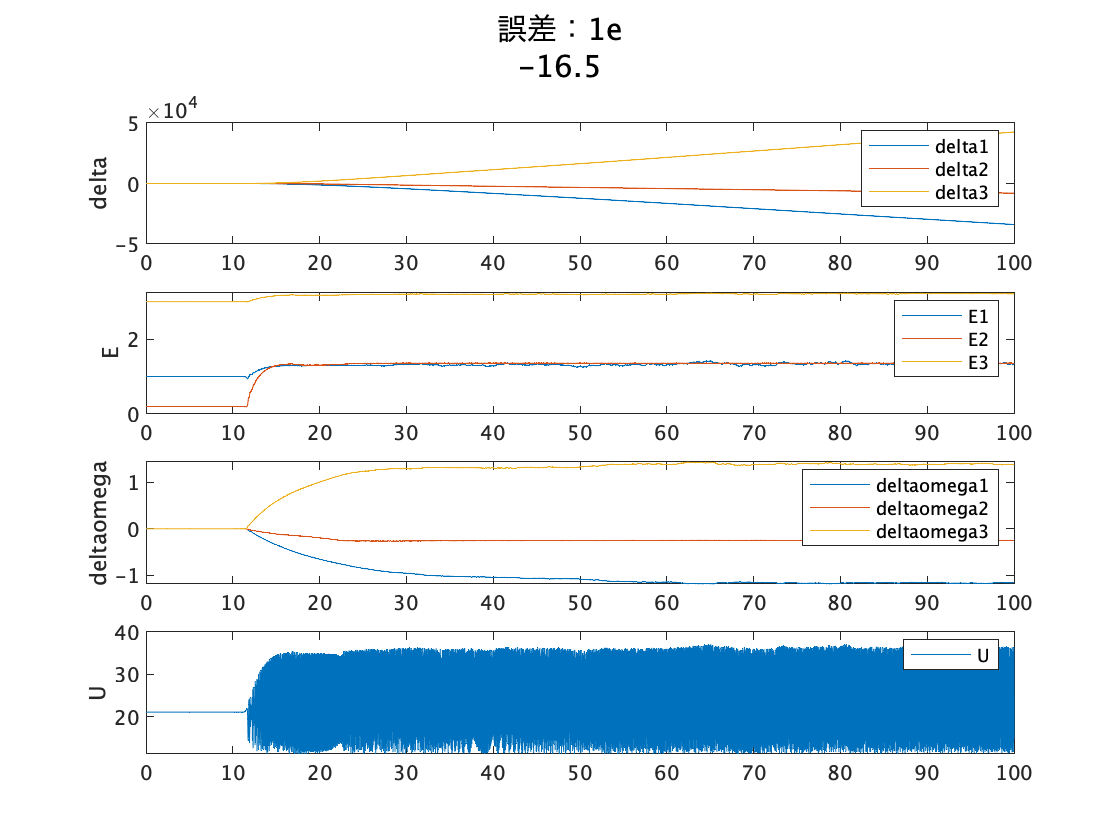

initial_delta = 	1.0e+-16 *

         0         0         0
    0.2776   -0.2776         0
         0         0         0


final_delta = 	1.0e+04 *

   -3.3931    0.0000   -0.0001
   -0.7975    0.0001   -0.0000
    4.2527    0.0000    0.0001


for cnt = -16:-0.1:-16.5

tspan = [0 100];

initial_delta = [1;0.1;3];
initial_E = [1;0.2;3];
initial_deltaomega = [0;0;0];
initial_generator_state = [initial_delta; initial_E; initial_deltaomega];

error = 10.^cnt;
steady_generator_state = initial_generator_state + [1;-1;1;-1;1;1;0;0;0]*error;

generator_state_ode_solver_for_livescript
sgtitle(["誤差：1e",cnt])
initial_error = initial_generator_state - steady_generator_state;
initial_error = reshape(initial_error, 3, 3)
final_error = transpose([delta(end,:) E(end,:) deltaomega(end,:)]) - steady_generator_state;
final_error = reshape(final_error,3,3)
if final_error == zeros(3)
    break
end
end

上記の探索

ans = 3

ans =    -19   -10


ans = 4.6587e+04

ans = 1

ans =   -19.0000  -14.5000


ans = 4.2848e+04

ans = 1

ans =   -19.0000  -16.7500


ans = 4.2527e+04

ans = 1

ans =   -19.0000  -17.8750


ans = 0

ans = 2

ans =   -17.8750  -16.7500


ans = 4.2527e+04

ans = 1

ans =   -17.8750  -17.3125


ans = 0

ans = 2

ans =   -17.3125  -16.7500


ans = 4.2527e+04

ans = 1

ans =   -17.3125  -17.0312


ans = 1.3878e-17

ans = 1

ans =   -17.3125  -17.1719


ans = 0

ans = 2

ans =   -17.1719  -17.0312


ans = 1.3878e-17

ans = 1

ans =   -17.1719  -17.1016


ans = 1.3878e-17

ans = 1

ans =   -17.1719  -17.1367


ans = 1.3878e-17

ans = 1

ans =   -17.1719  -17.1543


ans = 1.3878e-17

ans = 1

ans =   -17.1719  -17.1631


ans = 0

ans = 2

ans =   -17.1631  -17.1543


ans = 1.3878e-17

ans = 1

ans =   -17.1631  -17.1587


ans = 1.3878e-17

ans = 1

ans =   -17.1631  -17.1609


ans = 0

ans = 2

ans =   -17.1609  -17.1587


ans = 1.3878e-17

ans = 1

ans =   -17.1609  -17.1598


ans = 0

ans = 2

ans =   -17.1598  -17.1587


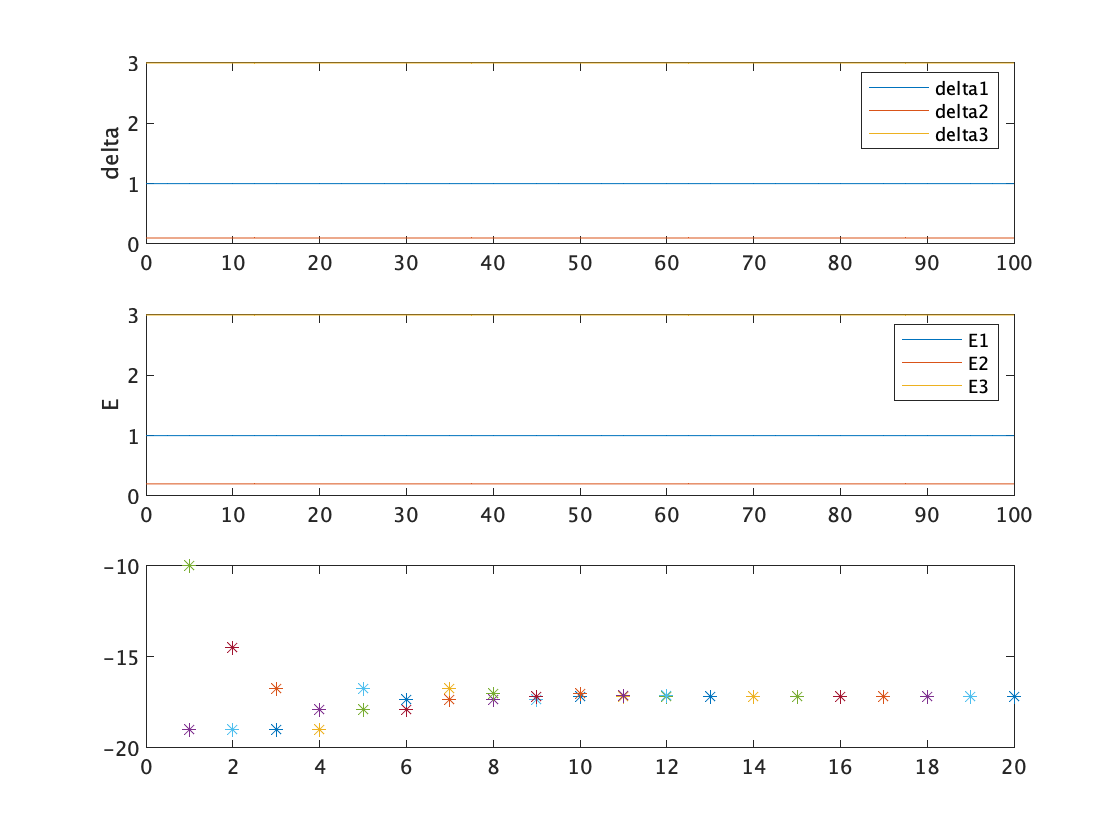

ans = 1.3878e-17

ans = 1

ans = 4

clear
left = -10;
right = -1;

tspan = [0 100];

initial_delta = [1;0.1;3];
initial_E = [1;0.2;3];
initial_deltaomega = [0;0;0];
initial_generator_state = [initial_delta; initial_E; initial_deltaomega];

get_final_error_wrap = @(error) get_final_error(error,tspan,initial_generator_state);

error_left = get_final_error_wrap(left);
error_right = get_final_error_wrap(right);

t = 1;
k = 1;
while t < 40
    
    if all(error_left(:)) == 0 & any(error_right(:)) ~= 0
        
        1
        
        right = (right + left) /2;
        
        if (right - left) < 0.001
            4
            break
        end
        
    elseif  all(error_right(:)) == 0
        
        2
        
        temp = left;
        
        left = right;
        
        right = right + (right - temp);
        
    elseif any(error_left(:)) ~= 0
        
        3
        
        temp = right;
        
        right = left;
        
        left = left - (temp - right);
      
    end
    [left, right]
    plot(t,[left;right],'*')
    hold on
    t = t + 1;
    
    error_left = get_final_error_wrap(left);
    error_right = get_final_error_wrap(right);
    
    max(abs(error_right(:)))
 
%{
    if max(error_right(:)) < 6
        right_array(k,1) = right;
        k = k + 1;
    end
%}
end

right_array

関数または変数 'right_array' が認識されません。

hold off
right
left

cnt = 1

cnt = 2

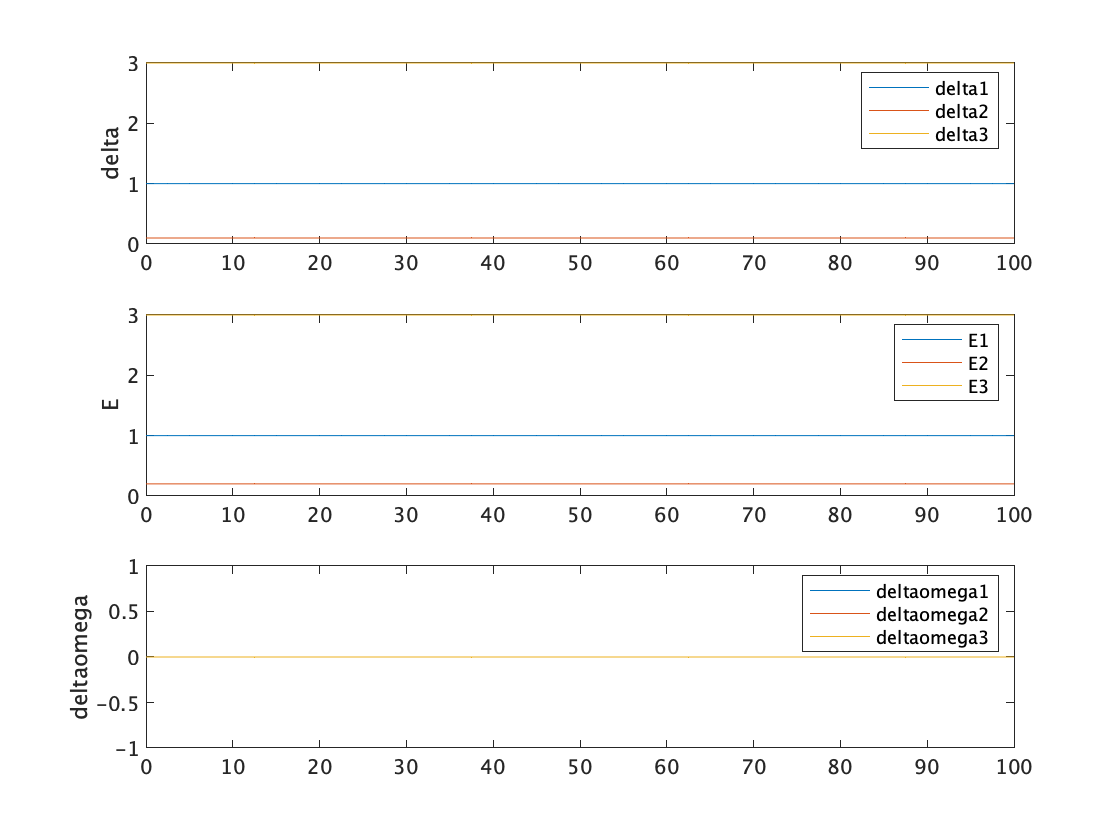

for cnt = 1:2
    cnt
    plot_generator_state(right_array(cnt),tspan,initial_generator_state)
  
end

plot_generator_state(left,tspan,initial_generator_state)
hold off